# qLab session IV:

## Intro:

On this Laboratory session we are going to work with the different attitude representations seen in class. 

- Exercise 1: 1 point. To be delivered before the end of the session.

- Exercise 2: 3 points

- Exercise 3: 3 points

- Exercise 4: 3 points

**Lab rules:**

- Always respect the delivery dates

- Use the templates when provided and DO NOT MODIFY THE FILE NAMES OR THE FUNCTION NAMES

- Verify that your code works before submit

- Always upload the files in a .zip with the name structure:  * Surname_Name.zip*

- Cheating is not allowed and will be firmly punished with a final mark of 0

This assignment is due to 

# Exercise 1:

The point p has coordinates

p_A = [3, 4]';

on a frame {A}, and coordinates

p_B = [-2.5, 0.5]';

on a frame {B}.

It is known that the angle between $x$-axis of frame {A} and the$y$ axes of the frame {B} is 30 deg counterclockwise.

##  1.1 Which are the coordinates of the origin of A seen from B?

pa_B = [cosd(-60) sind(-60); -sind(-60) cosd(-60)]*p_A;
corAfromB = p_B-pa_B

corAfromB =    -0.5359
   -4.0981


##  1.2 Which are the coordinates of the origin of B seen from A?

pb_A = [cosd(60) sind(60); -sind(60) cosd(60)]*p_B;
corBfromA = p_A-pb_A

corBfromA =     3.8170
    1.5849


##  1.3 Which are the coordinates of a point q expressed in A if 

q_B = [3,1]';
R=[cosd(60) sind(60); -sind(60) cosd(60)];
qb_A=R*q_B;
q_A=corBfromA + qb_A

q_A =     6.1830
   -0.5131


# Exercise 2:

 Let {A}, {B} and {C}, be 3 different reference frames. From them we know that:

- The origin of B with respect A is

AoB = [3,1,-2]';

- The origin of C with respect B is

BoC = [-3, 1,-2]';

- The three frames has different orientations in space. In fact:  

- The set of Euler angles stored in $\eta$ as $\eta = (\psi,\theta,\phi)$

eta = [25;145;30]; % Expressed in degrees

                 represent 3 consecutive rotations about z, y, and x respectively that allows to transform vectors from {A} to {B}  (which imply $^B v = R(\psi, \theta, \phi)\, ^Av$)

- The quaternion

q = 1/7*[-sqrt(3)*3.5;3;-1;-1.5];

                 allows to express in {B} a vector defined in {C}, if {C} and {B} had the same origin

Let in addition v1 and v2 to be points which coordinates are known in  {C}.

v1_C = [0;2;0];
v2_C = [0;2;5];

With the information provided above determine:

##  2.1.1 The affine** expression** that allows to relate a vector originally given in {C} to {B}. Note that no calculations have to be provided here, only the expression which is not a matrix.

- v_B = ( q * v_C * q' )

## 2.1.2 Implement a function called rotVbyq that provided a vector and a quaternion rotates the vector using quaternion multiplications. Test it and commet why do you think it is well implemented.

q0 = q(1);
qv = q(2:4);
v = v1_C;
rotVbyq = (q0^2 - qv'*qv)*v + 2*(v'*qv)*qv + 2*q0*(cross(qv,v));

##  2.2 The affine matrix that allows to express a vector originally given in {C} to {A}.

a1 = eta(1);
a2 = eta(2);
a3 = eta(3);

c1 = cosd(a1);
c2 = cosd(a2);
c3 = cosd(a3);
s1 = sind(a1);
s2 = sind(a2);
s3 = sind(a3);

R_AtoB = [c2*c1, c1*s2*s3-c3*s1, c1*c3*s2+s1*s3; c2*s1, s1*s2*s3+c3*c1, s1*s2*c3-c1*s3; -s2, c2*s3, c2*c3];
R_BtoA = R_AtoB';
I3 = [1,0,0;0,1,0;0,0,1];
R_CtoB = (q0^2-qv'*qv)*I3 + 2*(qv*qv') + 2*q0*[0,-qv(3),qv(2);qv(3),0,-qv(1);-qv(2),qv(1),0];

R_CtoA = R_BtoA*R_CtoB;

## 2.3 The vectors v1_C and v2_C form a segment. Make a 3d plot (plot3() in matlab), representing how the segment is seen on {A} in red, on {B} in blue and on {C} in green.

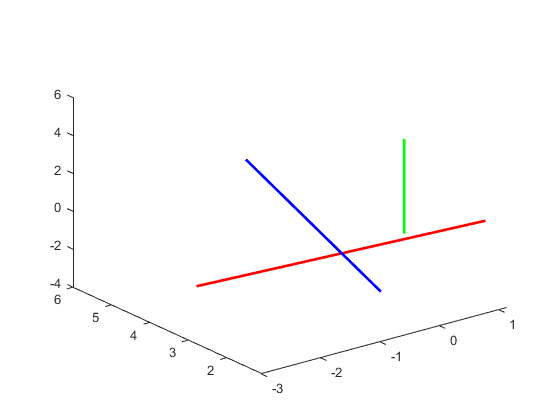

v1_B = R_CtoB*v1_C;
v2_B = R_CtoB*v2_C;

v1_A = R_CtoA*v1_C;
v2_A = R_CtoA*v2_C;

plot3([v1_A(1);v2_A(1)], [v1_A(2);v2_A(2)], [v1_A(3);v2_A(3)], 'Color', 'red', "LineWidth", 2);
hold on;
plot3([v1_B(1);v2_B(1)], [v1_B(2);v2_B(2)], [v1_B(3);v2_B(3)], 'Color', 'blue', "LineWidth", 2);
hold on;
plot3([v1_C(1);v2_C(1)], [v1_C(2);v2_C(2)], [v1_C(3);v2_C(3)], 'Color', 'green', "LineWidth", 2);
hold off;

# Exercise 3:

The points described by the columns of the matrix A 

A = load('AEx3.mat');
A = A.A;

are points contained into a circle, and they are defined in a world frame W.

A camera is situated at point

wc = [1; 6; 1];

 defined in the world frame. Moreover the orientation of this camera frame is achieved by rotating the world frame 90 degs about its y axis followed by -20 degrees about the resulting z axis.

If the camera has a focal length of 1/34 m:

##  3.1 Make a plot with the view of the points of the circle projected into the camera plane.

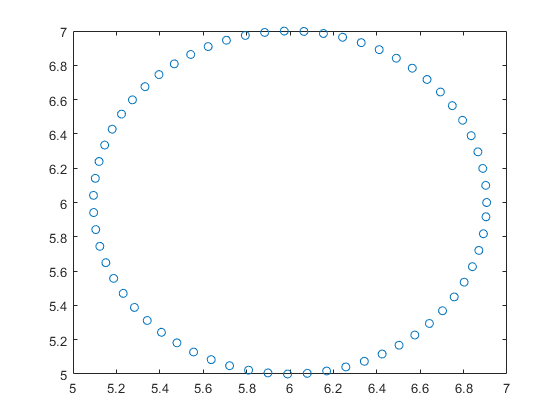

x = A(1,:); 
y = A(2,:);
z = A(3,:);
plot(x,y,'o')

##  3.2 Make also a 3D plot where all the scene is drawn in the world coordinates. The scene must contain the 2 reference frames (2 orthogonal sets of vectors) and the circle points. 

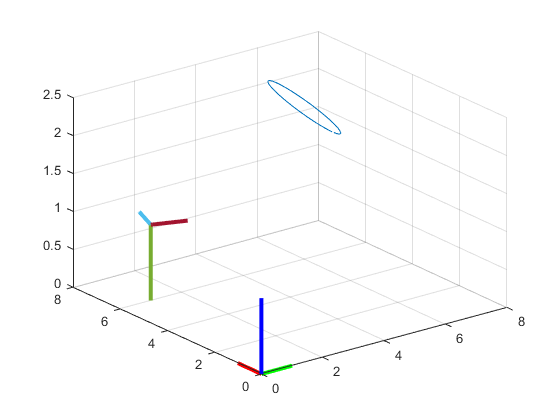

% First of all i want to get the rotation matrix. I used the function given
% in the last assigment.
[R] = eAngles2rotM(-20,90,0);
%Then, we rotate the given 'wc' mutipy it by 'R'
wc_rotated1=R*[1;0;0];
wc_rotated2=R*[0;1;0];
wc_rotated3=R*[0;0;1];
% Meanwhile, we print the circle with a plot 3d to see it's prespective
plot3(x,y,z,'-')

hold on; %we hold it to print the frames

v1=[0,0]; %i created this vector to save putting all the time [0,0]
%Now i do the plot of the first frame positioned at [0,0,0]
plot3(v1,[0,1],v1,"-r",'LineWidth',3)
plot3(v1,v1,[0,1],"-b",'LineWidth',3)
plot3([0,1],v1,v1,"-g",'LineWidth',3)

%we have the rotated vector 'wc'. Now we have to position it in the world.
%So in the first position we put the 'wc' given and in the next slot, we
%put the direction of the rotated frame. We add it to the 'wc' because we
%need the reference.
wc1=[wc,wc + wc_rotated1];
wc2=[wc,wc + wc_rotated2];
wc3=[wc,wc + wc_rotated3];
%now, time to plot!
plot3(wc1(1,1:2),wc1(2,1:2),wc1(3,1:2),'LineWidth',3)
plot3(wc2(1,1:2),wc2(2,1:2),wc2(3,1:2),'LineWidth',3)
plot3(wc3(1,1:2),wc3(2,1:2),wc3(3,1:2),'LineWidth',3)

grid on;
hold off;

You can use the provided function cameraproj.

# Exercise 4:

The columns of the next matrix, represents the coordinates od 4 points defined in a world frame.

A = load('AEx4.mat');
A = A.A

A =     0.9115    3.7207    1.9659    2.6663
    1.9397    2.8794    1.0000    3.8191
    3.3304    4.4372    3.2588    4.5087


From this 4 points, two segments are defined. The segment one, goes from the point defined by the first column to the point defined by the second column. The second segment is defined by the other two points.

 A camera frame is seeing the scene. The origin of the world frame seen from the camera frame is given by the vector

wc = [4.665;3.735;-0.5395];

And the orientation of the camera frame is obtained after rotating the world frame -150 degs about the direction

u = [0.01;-.2;1];

With the data provided determine:

## 4.1 The minimum angle that both segments forms (hint, they intersect)

v1 = A(:,2)-A(:,1);
v2 = A(:,4)-A(:,3);
angle = acosd(dot(v1,v2)/(norm(v1)*norm(v2)));

## 4.2 The angle that both segments forms in the image plane

%los puntos estan vistos desde el world, asi que hay que pasarlos a verlos desde la camara
%la idea es que cada punto es la suma de distancia entre camara y world más la de world al punto
%la distancia de world a los 4 puntos forma 4 vectores que tenemos que girar 150 grados para que sean vistos desde la cam
%una vez sepamos los puntos respecto a la camara es repetir los calculos del apartado anterior
p1 = A(:,1);
p2 = A(:,2);
p3 = A(:,3);
p4 = A(:,4);

p1_cam = p1*cosd(150) + (1-cosd(150))*(p1'*u)*u + cross(u,p1)*sind(150) + wc;
p2_cam = p2*cosd(150) + (1-cosd(150))*(p2'*u)*u + cross(u,p2)*sind(150) + wc;
p3_cam = p3*cosd(150) + (1-cosd(150))*(p3'*u)*u + cross(u,p3)*sind(150) + wc;
p4_cam = p4*cosd(150) + (1-cosd(150))*(p4'*u)*u + cross(u,p4)*sind(150) + wc;

v1_cam = p2_cam - p1_cam;
v2_cam = p4_cam - p3_cam;

angle_cam = acosd(dot(v1_cam,v2_cam)/(norm(v1_cam)*norm(v2_cam)));

## 4.3 Deliver a 3D representation of the scene with all the coordinates refered to the world frame

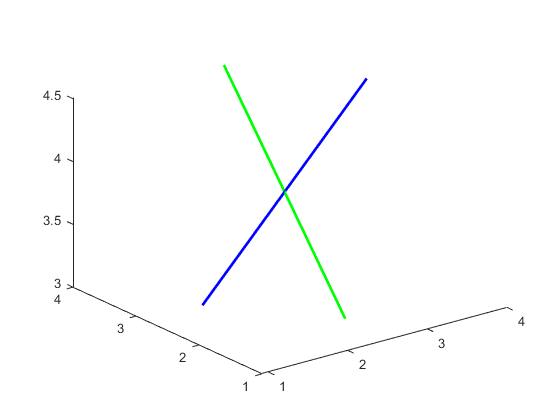

plot3([p1(1);p2(1)], [p1(2);p2(2)], [p1(3);p2(3)],'Color', 'blue', "LineWidth", 2);
hold on;
plot3([p3(1);p4(1)], [p3(2);p4(2)], [p3(3);p4(3)],'Color', 'green', "LineWidth", 2);
hold off;

## 4.4 Deliver the same 3D scene representations but with all the coordinates refered to the camera frame

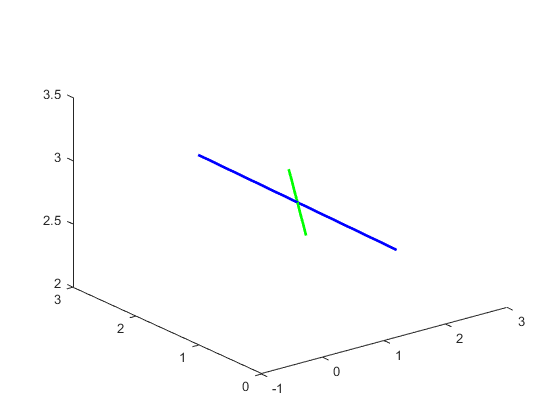

plot3([p1_cam(1);p2_cam(1)], [p1_cam(2);p2_cam(2)], [p1_cam(3);p2_cam(3)],'Color', 'blue', "LineWidth", 2);
hold on;
plot3([p3_cam(1);p4_cam(1)], [p3_cam(2);p4_cam(2)], [p3_cam(3);p4_cam(3)],'Color', 'green', "LineWidth", 2);
hold off;